Colin Keenan

ECE 5470

5-13-2020

# Homework 12

1.  Edge Detection

## Sobel Filter

clear; close all;

fprintf("Question 1:")

Question 1:

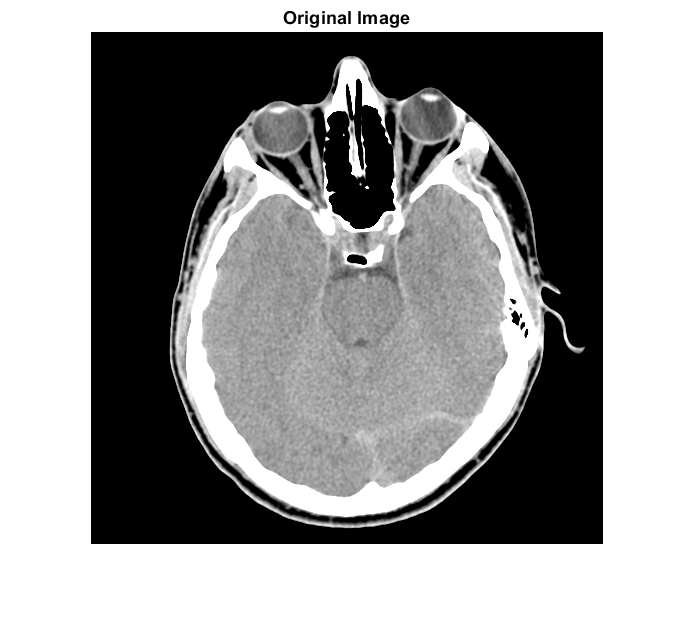


image = im2double(imread('Fig12-1.tif'));

sobel_y = [[-1 -2 -1]
           [ 0  0  0]
           [ 1  2  1]];
       
sobel_x = [[-1 0 1]
           [-2 0 2]
           [-1 0 1]];
       
LoG = [[-1 -1 -1]
       [-1  8 -1]
       [-1 -1 -1]];

image_sobel_x = filter(image,sobel_x);       
image_sobel_y = filter(image,sobel_y);    
image_sobel = sqrt(image_sobel_x.^2 + image_sobel_y.^2);
image_LoG = filter(image,LoG);

threshold = 20/255;

transform = 1:256;
for x = 1:256
    if(x <= threshold*255)
        transform(x) = 0;
    else
        transform(x) = 255;
    end
end

image_LoG_thresh = applyThreshold(image_LoG,threshold);
image_LoG_thresh_0X = zeroXthreshold(image_LoG_thresh);

figure;
imshow(image);
title("Original Image")

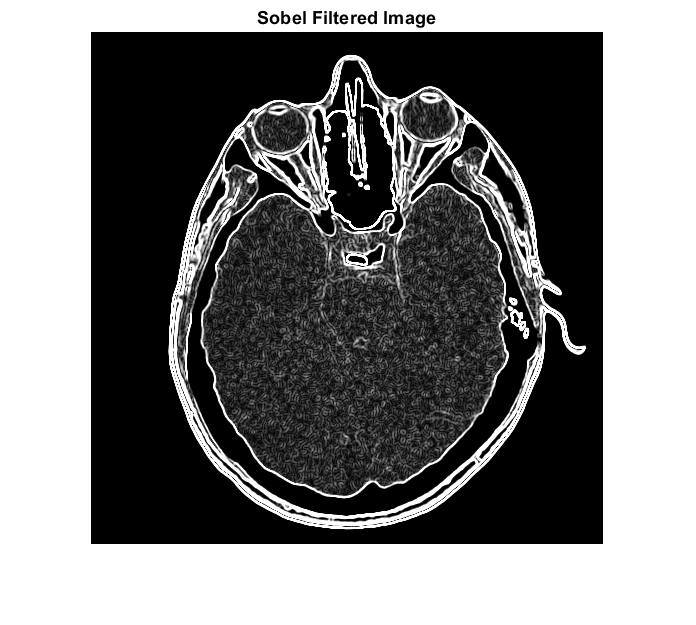


figure;
imshow(image_sobel);
title("Sobel Filtered Image")

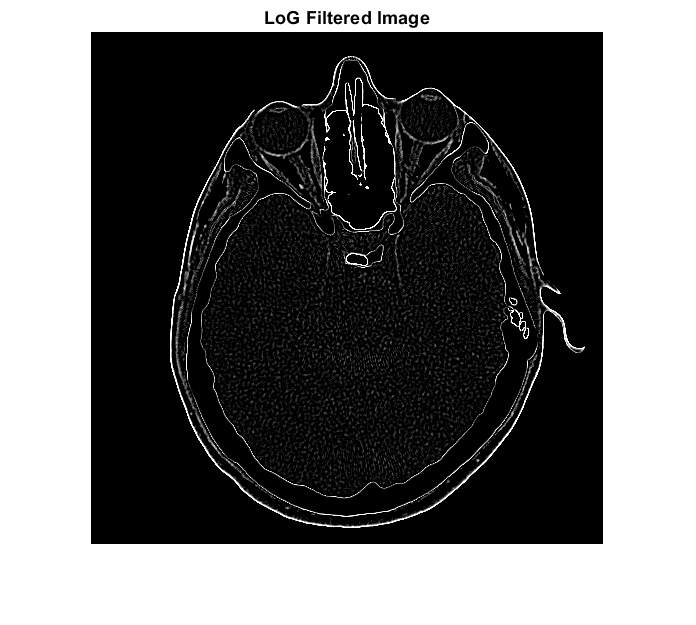


figure;
imshow(image_LoG);
title("LoG Filtered Image")

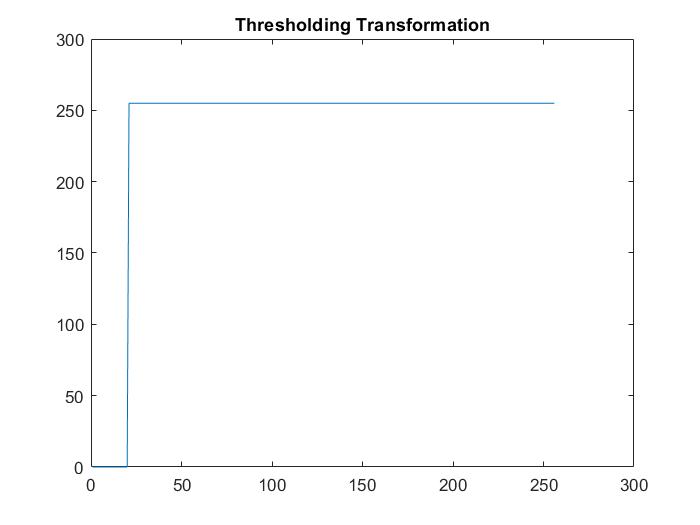


figure;
plot(transform);
title("Thresholding Transformation");

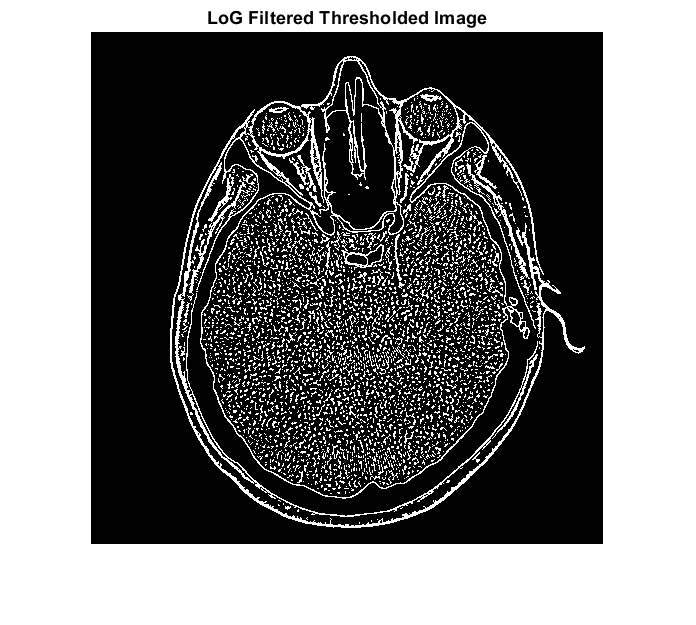


figure;
imshow(image_LoG_thresh);
title("LoG Filtered Thresholded Image")

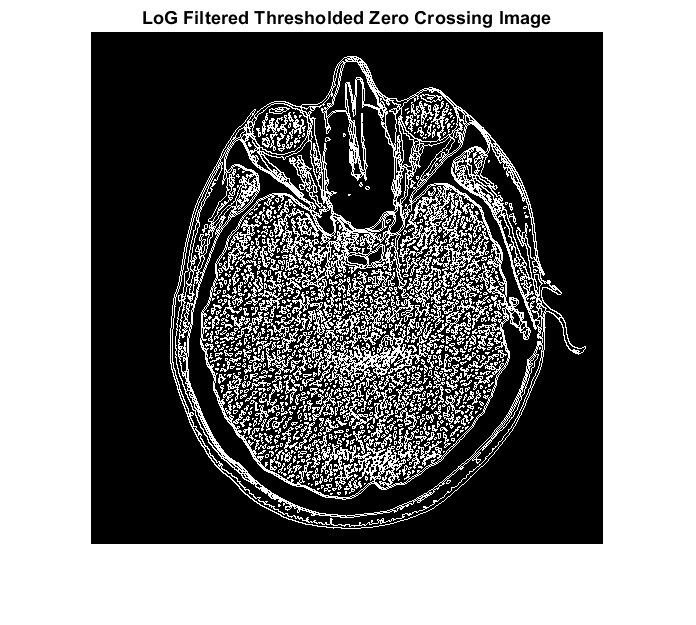


figure;
imshow(image_LoG_thresh_0X);
title("LoG Filtered Thresholded Zero Crossing Image")

2. Thresholding

clear; close all;

fprintf("Question 2:")

Question 2:

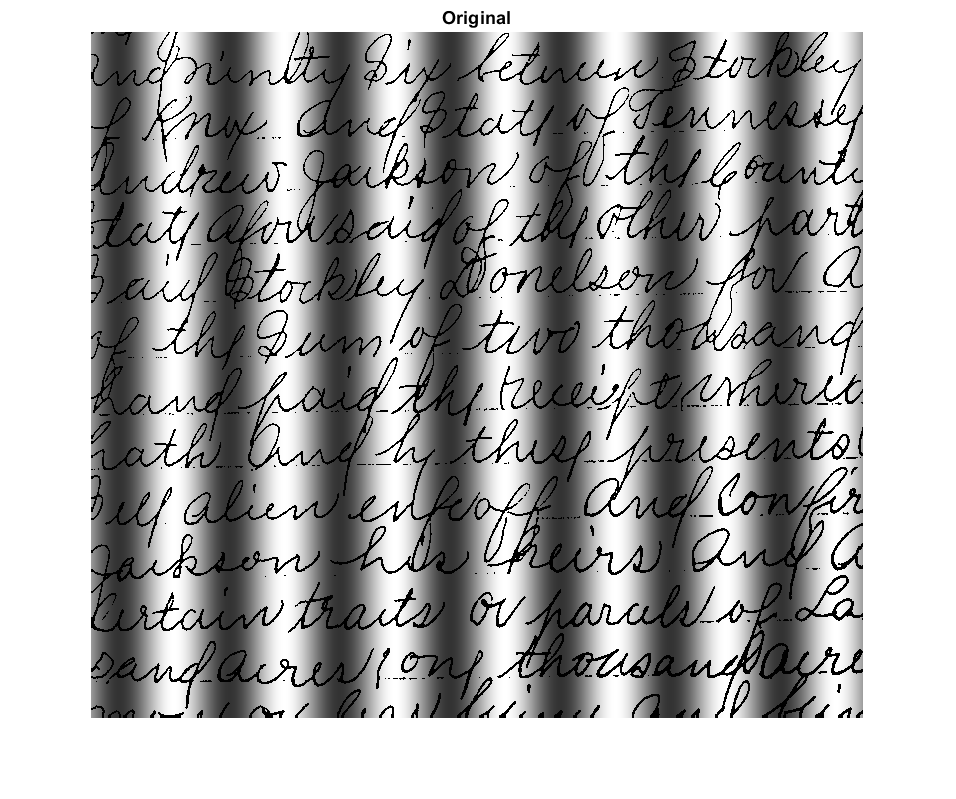


image = imread('Fig12-2.tif');

[S, cS, eS] = cceFourierSpec(image);

C0_1 = 7;
W_1 = 0.001;
GBRF_1 = gbrf(image, C0_1, W_1);

[fS, fcS, feS] = cceFourierSpec(GBRF_1);

threshold = 100/255;

transform = 1:256;
for x = 1:256
    if(x <= threshold*255)
        transform(x) = 0;
    else
        transform(x) = 255;
    end
end

image_thresh = applyThreshold(GBRF_1,threshold);

% Original Images
figure;
imshow(image);
title("Original");

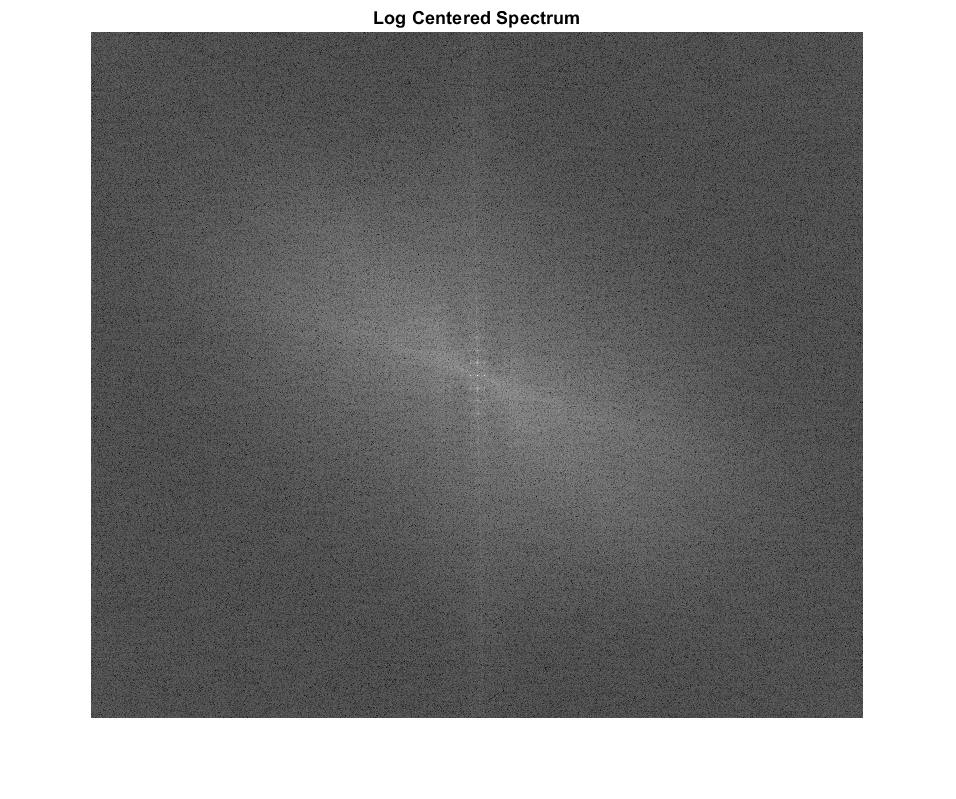


% Enhanced Centered Spectrums
figure;
imshow(eS, []);
title("Log Centered Spectrum");

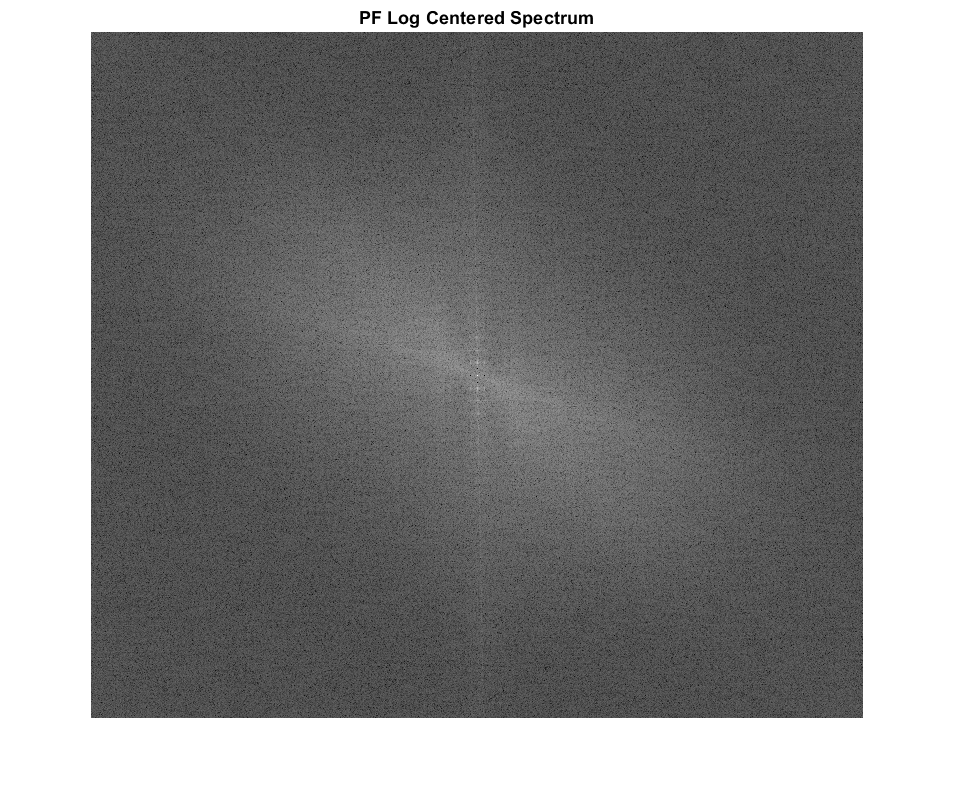


% Post Filter Centered Spectrums
figure;
imshow(feS, []);
title("PF Log Centered Spectrum");

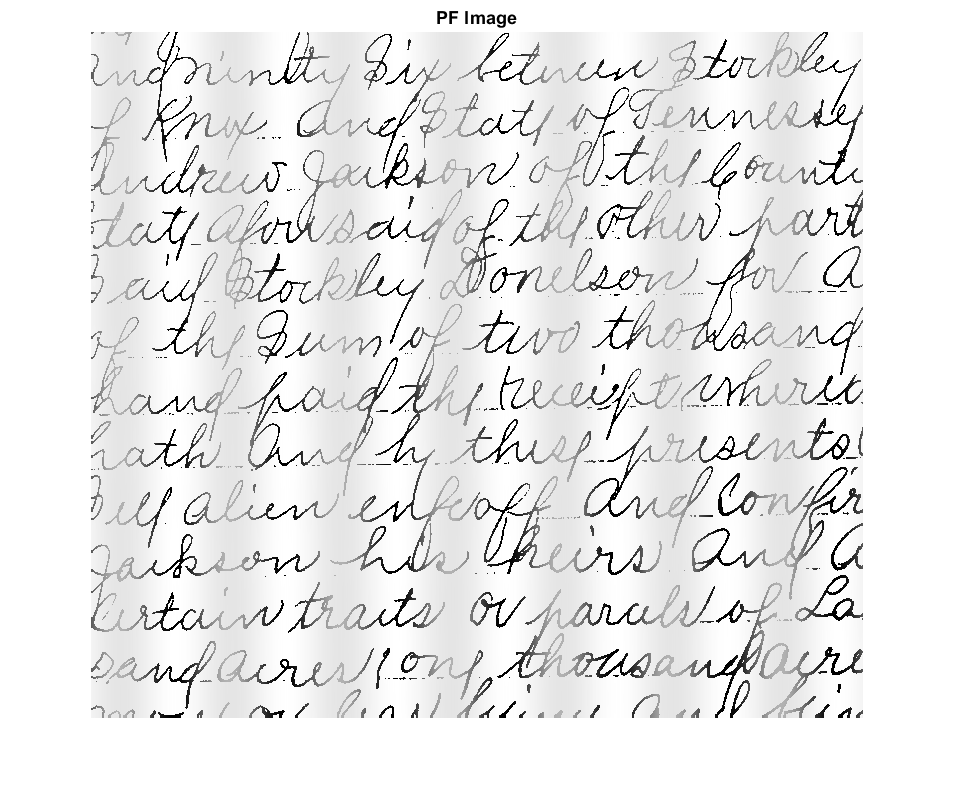


% Post Filter Images
figure;
imshow(GBRF_1, []);
title("PF Image")

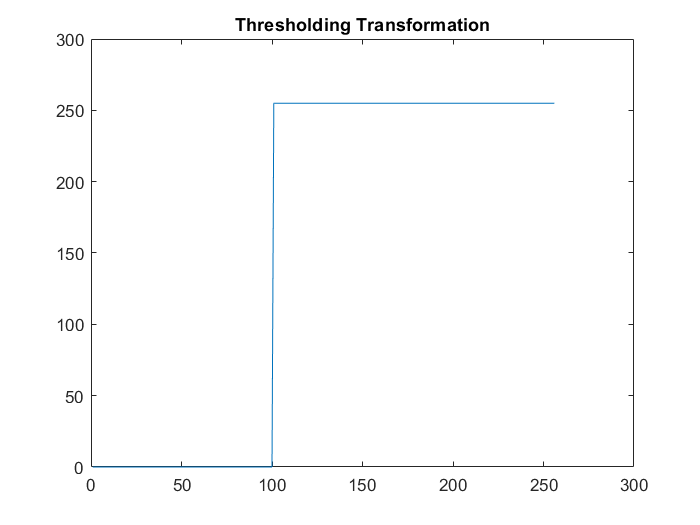


figure;
plot(transform);
title("Thresholding Transformation");

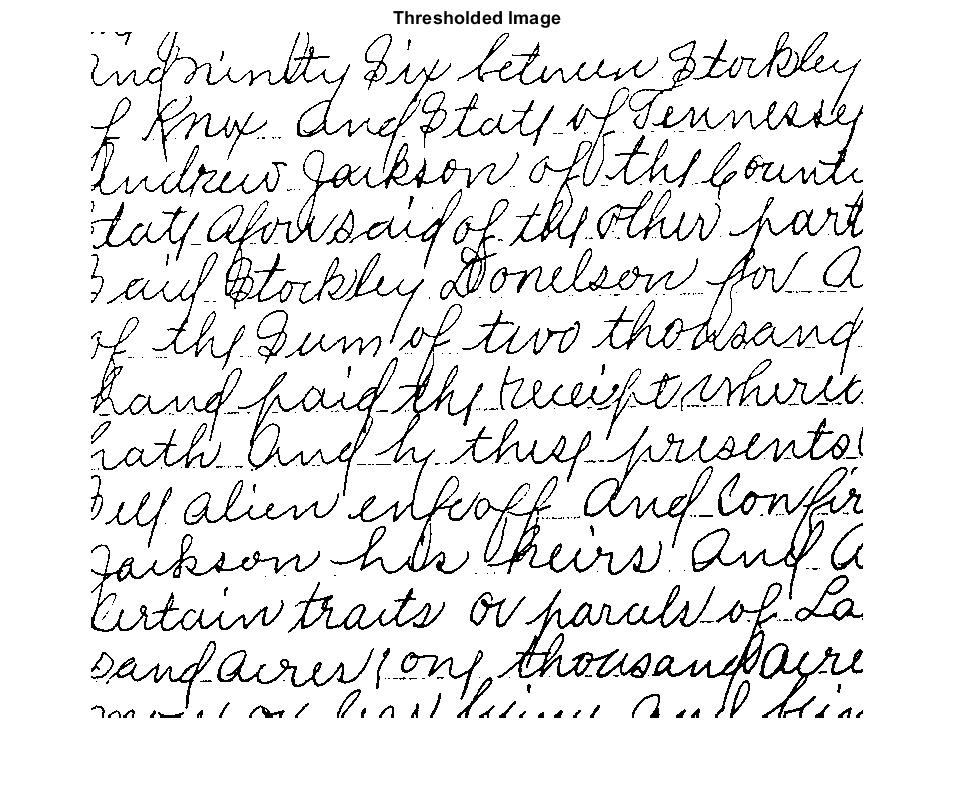


figure;
imshow(image_thresh);
title("Thresholded Image");

## Appendix (Functions Used)

function filtered = filter(image, struct)
    filtered = zeros(size(image));
    pad = floor(size(struct,1)/2);

    for i = 1+pad : size(image,1)-pad
        for j = 1+pad : size(image,2)-pad
            
            % Get Current Frame
            frame_3x3 = [[image(i-1,j-1) image(i-1,j+0) image(i-1,j+1)]
                         [image(i+0,j-1) image(i+0,j+0) image(i+0,j+1)]
                         [image(i+1,j-1) image(i+1,j+0) image(i+1,j+1)]];
           
            masked_3x3 = frame_3x3 .* struct;
            filtered(i,j) = sum(sum(masked_3x3));
        end
    end
end

function [S,cS,eS] = cceFourierSpec(imag)
% Description: Compute, Center, and Enhance a Fourier Spectrum of an Image

% Base FFT
F = fft2(im2double(imag));

% Spectrum
S = abs(F);

% Centered Spectrum
cF = fftshift(F);
cS = abs(cF);

% Enhanced Spectrum
eS = log(1+abs(cF));
end

%%%%%%%%% Band Reject Filters %%%%%%%%%
function filtered = gbrf(imag, C0, W)
% Description: Perform an Gaussian Band Reject Filter to an image with the given
% Center and Width of the band

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Gaussian Filter
H = 1-exp(-(((D-C0).^2)./(D.*W^2)));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end

function thresholded = applyThreshold(image,border)
    thresholded = zeros(size(image));
    
    for i = 1:size(image,1)
        for j = 1:size(image,2)
            r = image(i,j);
            if(r <= border)
                thresholded(i,j) = 0;
            else
                thresholded(i,j) = 1;
            end
        end
    end
end

function zeroXoutput = zeroXthreshold(image)

[M,N] = size(image);

zeroXoutput1(1,1) = 0;
zeroXoutput2(1,1) = 0;
for x = 1:M
    for y = 1:N
        %x direction
        if (x == 1) && (y == 1)
            currentValue = image(x,y);
        elseif (image(x,y) ~= currentValue)
            zeroXoutput1(x,y) = 1;
            currentValue = image(x,y);
        elseif (image(x,y) == currentValue)
            zeroXoutput1(x,y) = 0;
        end

    end
end

for y = 1:N
    for x = 1:M
        %y direction
        if (x == 1) && (y == 1)
            currentValue = image(x,y);
        elseif (image(x,y) ~= currentValue)
            zeroXoutput2(x,y) = 1;
            currentValue = image(x,y);
        elseif (image(x,y) == currentValue)
            zeroXoutput2(x,y) = 0;
        end

    end
end

zeroXoutput = zeroXoutput1 | zeroXoutput2;

end